%% 3.5 Using Third-Party Libraries in MATLAB

% 3.5.1 JFreeChart and Other Charting Libraries
% An extremely powerful and widely used Swing-based class library is JFreeChart
%   (www.jfree.org), which includes classes for
%   displaying charts, graphs, and gauges in Java panels.
% JFreeChart solves MATLAB's limitation that plot axes cannot be added to Java containers.
% JFreeChart is free open-source under the GNU LGPL license.
% Used by over 40,000 Java developers worldwide
%   (as well as by some MATLAB developers),
%   it is in constant development and improvement.

% JFreeChart has some limitations compared with MATLAB plots,
%   but it can do things that are extremely difficult to achieve in MATLAB,
%   as shown in the following screenshots:
% ... (Omitted)

% Let us now integrate a JFreeChart pie chart within a MATLAB figure,
%   as a means of illustrating how to
%   integrate third-party Swing-derived components into MATLAB.

% First, download the latest JFreeChart version from its download page
%   on the open-source repository www.sourceforge.net.
% Next, unzip the downloaded file into some new folder.
% Now, edit classpath.txt (or use javaaddpath) to load
%   jfreechart-1.0.13.jar and jcommon-1.0.16.jar
%   (which are located in the /lib/ subfolder) to the Java classpath
%   (replace the version numbers as appropriate):

... (Lots of issues are omitted)

% 3.5.6 A Note of Caution
% A note of caution is due when integrating external Java class libraries
%   in MATLAB applications:
%   not all libraries were developed and debugged with the same amount of attention
%   to detail, quality, and public feedback as the Swing libraries.
% Some libraries may have internal bugs, inaccuracies, memory leaks,
%   and all sorts of other similar malfunctions.
% These may affect the stability, behavior, and accuracy
%   of any MATLAB application that integrates these libraries.
% In some cases, the original library creator may no longer be supporting this package;
%   in other cases, the level of support cannot be guaranteed.
% For this reason, I personally prefer, wherever possible,
%   to use an open-source library that has thousands of active users worldwide.
% This large user base could provide answers, workaround,
%   and/or support in case of need.
% This appears to be more advisable than using a library from some obscure provider.
% While this general caution and advice is true for all integrations
%   of any external software component,
%   it is especially important with the MATLAB-Java interface,
%   which is lacking in documentation, support, and decent debugging tools.
% Tracing problems across the MATLAB-Java interface can be
%   a painful and frustrating experience indeed.
% As a case in point, a CSSM poster asked the MATLAB community's help
%   in solving a memory leak problem in what he thought was the MATLAB-Java interface,
%   but which later turned out to be internal leaks
%   within the external Java library(in this specific case —jPar).

%% 3.6 System-Tray Icons

% Java 1.6, available since MATLAB 7.5 (R2007b),
%   enabled programmatic access to system-tray icons on such systems
%   that supported system tray.
% If the SystemTray object indicates that it isSupported,
%   then a Tray Icon can be added,
%   along with an associated tooltip and popup menu (See color insert.):


% sysTray = java.awt.SystemTray.getSystemTray;
% if (sysTray.isSupported)
%     myIcon= fullfile(matlabroot, 'toolbox/MATLAB/icons/MATLABicon.gif') ;
%     iconImage = java.awt.Toolkit.getDefaultToolkit.createImage(myIcon) ;
%     trayIcon=java.awt.TrayIcon(iconImage, 'initial tooltip');
%     trayIcon.setToolTip('click this icon for applicative context menu');
%     java.awt.SystemTray.getSystemTray.add(trayIcon); % remove(trayIcon)
% end

java.awt.SystemTray.getSystemTray.remove(trayIcon);

% The icon image can be made to automatically resize to the system-tray dimensions, 
%   using the traylcon.setlmageAutoSize(true) method 
%   (by default, the icon image will maintain its original size, 
%   getting cropped or appearing small as the case may be).

% Of course, after initial setup, all the tray icon's properties 
%   (icon image, popup, tooltip, etc.) can be modified with convenient set() methods 
%   (setlmage, setPopupMenu, setTooltip) or via MATLAB's set() function 
%   (set(handle(trayIcon),..., ...)). 
% Tray icons have several important functionalities, 
%   which provide very important visual cues for application users 
%   in a very non-obtrusive manner: 

%% 3.7 Drag-and-Drop 

% 3.7.1 Data Transfer Mechanism in MATLAB 

% Drag-and-drop (DND), together with cut-copy-and-paste (CCP), 
%   collectively called Data Transfer (DT), 
%   are standard functionalities in modern GUI applications. 

% Unfortunately, MATLAB's support of these has historically been lacking.
% Some degree of DT support is available in MATLAB. 
% For example, we can CCP text into a textbox uicontrol 
%   and use DND with GUIDE or the MATLAB desktop.
% However, CCP is often lacking (e.g., we cannot paste into a MATLAB figure or plot) 
%   and DND is missing altogether from figure components (axes and controls). 

% This omission was apparently intentional,
%   because MathWorks took the trouble to ensure DND and CCP behavior 
%   for some of its internal tools (e.g., in tstool, MATLAB's timeseries tool).
% I cannot but wonder why MathWorks chose not to include DT functionality 
%   as a generally supported functionality in its HG library. 

% Over the years, sporadic attempts were made by posters on CSSM and File Exchange 
%   to provide DT support. 
% Of these, some were platform-specific (using Windows-specific ActiveX calls),
%   whereas others were source- or target-limited 
%   (e.g., limiting their support to axes and figures or to files 
%    dropped onto the desktop143). 
% An unsuccessful attempt to integrate Java-based DND was reported on CSSM.
% I am not familiar with any generic cross-application DT solution in MATLAB 
%   (e.g., DND or CCP of an image from the computer's browser 
%    onto a uicontrol or axes). 

% This section presents a generic cross-platform solution for incorporating DT in MATLAB. 
% It relies on Java Swing's support for DT:
%   since MATLAB GUI is essentially Swing-based,
%   Swing's DT functionality can be adapted to all MATLAB GUI elements. 

% DND configuration requires three distinct steps: 
% - Define draggable source components and allowed actions (copy/move/link). 
% - Define droppable target components and their internal drop location. 
% - Define callback actions to invoke when a source is dropped onto a target. 

% Not all of these steps are mandatory. 
% For example, a component may only be droppable (=drag target) 
%   but not draggable (=drag source). 
% Some Java Swing components are not draggable- or droppable-enabled, 
%   although, in general, any component that we would expect to be draggable 
%   is already pre-enabled as such, and similarly for droppable.

% To be precise, this does not mean that these components are draggable/droppable
%   by default — only that they can be set as draggable/droppable 
%   if the programmer so chooses, without requiring any complex programming.
% In cases where DND support is not predefined 
%   (either as draggable or droppable or both), 
%   full DND support can be added to our custom Swing-extended class 
%   using customized programming.

% To set a Java Swing component as draggable (=possible drag source),
%   and assuming that the component is draggable-enabled,
%   use its setDragEnabled(true) method 
%   (the method may be called setDndEnabled() in some cases). 
% This also applies to all MATLAB uicontrols, 
%   since they use underlying Swing components.
% Non-MATLAB components (e.g., text strings) cannot be set draggableenabled, 
%   and rely on their internal (native) setting to determine 
%   whether or not they are draggable. 

% The way a drop location is displayed is affected 
%   by the component's setDropMode() method, 
%   which accepts javax.swing.DropMode.USE_SELECTION (the default value), 
%   DropMode.ON, DropMode.INSERT, or DropMode.ON_OR_INSERT.

% DropMode.ON mode enables dropping on top of (replacing) existing elements 
%   without modifying the current selection, as USE_SELECTION does; 
% DropMode.INSERT enables dropping between (i.e., inserting) elements; 
% DropMode.ON_OR_INSERT enables a combination of both, 
%   depending on the actual cursor pixel position. 
% Note that setting the drop mode is only possible since JVM 1.6, 
%   which is available in MATLAB R2007b (7.5) onward.

% Unfortunately, enabling DND is not nearly as easy as setting the DropMode.
% Things are even more complicated in MATLAB, 
%   which actually prevents regular DND from working within
%   regular MATLAB figure windows. 
% We shall see later how to bypass this limitation, 
%   but for the moment let us discuss the dropped-item side of the process. 
% To set a component as droppable, we need to assign it a java.awt.dnd.DropTarget. 
% Most MATLAB components return null ([]) in response to getDropTarget(). 
% In such cases, we need to assign a new DropTarget. 
% For example, let us set the axis canvas as droppable: 

warning('off', 'MATLAB:HandleGraphics:ObsoletedProperty:JavaFrame');
figure;
dnd = handle(java.awt.dnd.DropTarget(), 'CallbackProperties') ; 
jFrame = get(handle(gcf), 'JavaFrame'); 
jAxis = jFrame.getAxisComponent; 
jAxis.setDropTarget(dnd); 

% The DropTarget object contains the following properties: 
dnd.get

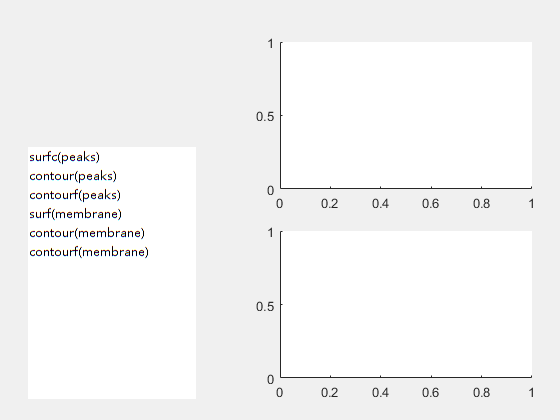

% 3.7.2 A Sample MATLAB Application That Supports DND
% Let us implement a simple DND GUI, 
%   in which a listbox contains some plotting commands, 
%   and the user can drag any of them onto one of the two axes. 
% For this example, we will use a standard MATLAB listbox uicontrol, 
%   demonstrating how DND behavior can be retrofitted to existing MATLAB GUIs, 
%   without any need to switch to Java components: 

% First prepare the figure 
hFig = figure('name','DND example','numbertitle','off');

% Add a listbox with several plotting commands
plotNames = {'surfc(peaks)','contour(peaks)','contourf(peaks)' , ...
    'surf(membrane)', 'contour(membrane)', 'contourf(membrane)'};

% (rather than use a MATLAB listbox uicontrol, directly use JList)

% hListbox = uicontrol('style','listbox', 'units','norm' , ...
% 'position', [.05, .05, .3, .6] , 'string',plotNames) ;
% jListbox = findjobj(hListbox,'nomenu');
% jListbox = jListbox.getviewport.getview; % in a scrollpane

jListbox = javax.swing.JList(plotNames);
[hjList,hcList] = javacomponent(jListbox, [10,10,100,200], hFig);
set(hcList, 'units', 'norm', 'position', [.05, .05, .3 , .6]);

% Add some plot axes
hAxl = axes('position', [.5, .1, .45, .35] ) ;
hAx2 = axes('position', [.5, .55, .45, .35]) ;


% Enable dragging from the listbox
jListbox.setDragEnabled(true);

% Enable drop on the figure axes
dnd = handle(java.awt.dnd.DropTarget(),'CallbackProperties');
jFrame = get(handle(hFig),'JavaFrame');
jAxis = jFrame.getAxisComponent;
jAxis.setDropTarget(dnd);
set(dnd,'DropCallback',{@dropCallbackFcn,hFig});
set(dnd,'DragOverCallback',@dragCallbackFcn);

% Define the drag movement callback function
% (See functions definitions at the end of this script)

% In some cases, implementation of DND in MATLAB fails to process drop events correctly. 
% The reason for this is that apparently MATLAB's default DropTargetListener 
%   seems to pass the DropTargetDropEvent (dtde) to MATLAB callback functions 
%   without previously accepting the drop, so dtde.getTransferable() fails 
%   and the drop event is ignored.
% This is apparently not an issue for internal MATLAB components, 
%   which override the standard DropTarget class. 

% Dirk Engel, who discovered this bug, also provided a suggested fix 
%   (overriding the DropTarget class), 
%   which is provided here with some modifications:

% ... (Omitted)

% A suggested exercise for adventurous readers is to 
%   implement a MATLAB figure that displays a plot axes 
%   and a JFileChooser Swing component side by side; 
% image files from the file chooser or from external applications 
%   (e.g., Windows Explorer) can be drag-and-dropped onto the axes, 
%   thereby displaying their image contents. 

function dragCallbackFcn(src,eventData)
try
    % Enable drop only on top of actual axes - not the entire figure
    hAxes = overobj('axes');
    if isempty(hAxes)
        eventData.rejectDrag;
    else
        eventData.acceptDrag(eventData.getDropAction);
    end
catch
    % never mind...
end
end

% Define the drop callback function
function dropCallbackFcn(src,eventData)
try
    hFig = varargin{3};
    transferable=eventData.getTransferable;  % will crash if invalid
    dataFlavorStr = 'text/plain; class=java.lang.String';
    dataFlavor = Java.awt.datatransfer.DataFlavor(dataFlavorStr);
    dataStr = transferable.getTransferData(dataFlavor);
    hAxes = overobj('axes');
    if -isempty(hAxes)
        axes(hAxes(1));
        eval(dataStr) ;
    end
    eventData.dropComplete(true);
catch
    % never mind...
end
end



